#  Lesson 3: Loops & Conditionals

Okay, now that we've learned how Loops and Conditonals work in theory, lets work on how to use them in our code. We'll write a simple code to display the numbers 1 through 5

%display the numbers 1 through 5 without using a loop




This took us 10 lines of code, but we can do it in way less using a `while `loop.

In MATLAB, loop syntax requires one line, with `while` or `for`, to initialize the condition of the loop. This is followed by the command(s) to execute within the loop, which must be tabbed over. To let MATLAB know the loop is over, we use the keyword `end`. 

%use a while loop to display the numbers 1-5 in less lines of code




Lets try to accomplish the same task using a `for` loop. For a `for` loop, the syntax is almost the same, but we need to specify an* iterable object* to act upon. 

%use a for loop to do this in even less lines of code 




The `for` loop can do it in even less lines. This is valuable, because the less lines of code you write, the less places there are for something to go wrong. 

So what is a practical use of loops?

Let's demonstrate using temperature data from Ann Arbor, from May 21 through June 4th (when I'm writing this). The data are measured in fahrenheit, and we want to convert to celsius.

%here are the data in fahrenheit
temps_f = [64,64,72,84,84,86,81,77,70,66,64,72,88,81,82];

Using a loop below, we can convert each temperature to celsius using only a few lines of code. Lets try this out.

%Create an empty array where we will store the celsius temps


%write a loop which will convert each of these to celsius
    %define the thing we want to iterate over
    %define our fahrenheit temperatures
    %tell MATLAB how to get the celsius temperatures
    %tell matlab how to store the celsius temperatures
%end the loop

So, by effectively using a for loop, we've been able to change every value in a dataset with only a few lines.

Lets also see how we can further this process using an if statement. Maybe we need to simplify this situation and just decide whether a given day was hot or not. We'll pick an arbitrary cutoff, and say that 80 degrees or higher is hot, and lower than 80 degrees isn't. 

%create an empty array where we will keep the hot or not variable


%write a loop, using conditionals, which can tell you which days were hot
%and which were not



By combining the loop with an if statement in this way, we're able to accomplish a lot of powerful things in MATLAB, the depths of which you'll surely find out about as you continue to code in MATLAB.

Now that we've gone through some less-neurosciency examples, lets put these skills to use in a more relevant dataset.

We'll use the same dataset we used for Lesson 2. I'll recreate the plot for it below, to jog your memory: 

%this is the same code from Lesson 2

%uncomment the below section to load the fluorescence data and view the
%plot from the last lesson

load('Fluorescence_data.mat')

figure;
ax1 = subplot(4,1,1);
plot(Fluorescence, 'k' );
title('Fluorescence');
ax2 = subplot(4,1,2);
plot(Lick_full, 'm');
title('Licking');
ax3 = subplot(4,1,3);
plot(Visual_full, 'b');
title('Visual Stimulus');
ax4 = subplot(4,1,4);
plot(Ensure_full, 'r' );
title('Ensure');
linkaxes([ax1 ax2 ax3 ax4],'x');

So, we've got the Fluorescence measured in the mouse's brain, the times a visual stimulus is shown, the times the mouse licks, and the times the food reward is delivered. The goal here is to understand whether the fluorescence corresponds to any of the other events; does the fluorescence level change each time the mouse sees the stim, or each time it licks? or does it only change when a food reward is delivered? 

In order to figure this out, we need to look at the fluorescence level surounding each of those events. We can do this specifically for the reward deliveries with for loops.

First, we're gonna find the baseline fluorescence F0 before each reward is given. 

initialize the array and accumulator variable to use in the loop

F0_per_reward = [];
acc_F0_reward = 1;


loop through and get the F0 for each ensure reward, by averaging fluorescence at an interval (-500 to -20) immediately before reward.

for F0_reward_idx = 1:length(Ensure_idx)
    e_onset = Ensure_idx(F0_reward_idx);
    F0_reward_window = (e_onset-500):(e_onset-20);
    F0_reward = mean(Fluorescence(F0_reward_window));
    F0_per_reward(acc_F0_reward) = F0_reward;
    acc_F0_reward = acc_F0_reward+1;
end 

Next, we're gonna find the level fluorescence immediately following the reward delivery, each time the reward is delivered: 

F_per_reward = [];
acc_F_reward=1;


loop through to calculate peak F values for fluorescence in the windows immediately following the ensure delivery, up to 6 seconds (6000 points) afterwards

for F_reward_idx = 1:length(Ensure_idx)
    e_onset = Ensure_idx(F_reward_idx);
    F_reward_window = (e_onset+1):(e_onset+(6 * Sampling_rate));
    F_reward = mean(Fluorescence(F_reward_window));
    F_per_reward(acc_F_reward) = F_reward;
    acc_F_reward = acc_F_reward+1;
end 

Lastly, for each instance of a reward delivery, we're gonna calculate the change in fluorescence after the reward, relative to before the reward. This is the deltaFluorescence/Fluorescence0, or the dFF. 

initialize array to use in loop

dFF_per_reward = [];


calculate dFF for each reward occurance

for dFF_reward_idx = 1: length(Ensure_idx)
    F_reward = F_per_reward(dFF_reward_idx);
    F0_reward = F0_per_reward(dFF_reward_idx);
    dFF_reward = (F_reward - F0_reward)/F0_reward;
    dFF_per_reward = [dFF_per_reward, dFF_reward];
end 


Now, we have values for the change in Fluorescence at each reward delivery. Lets plot those: 

plot the dFF values in a box plot

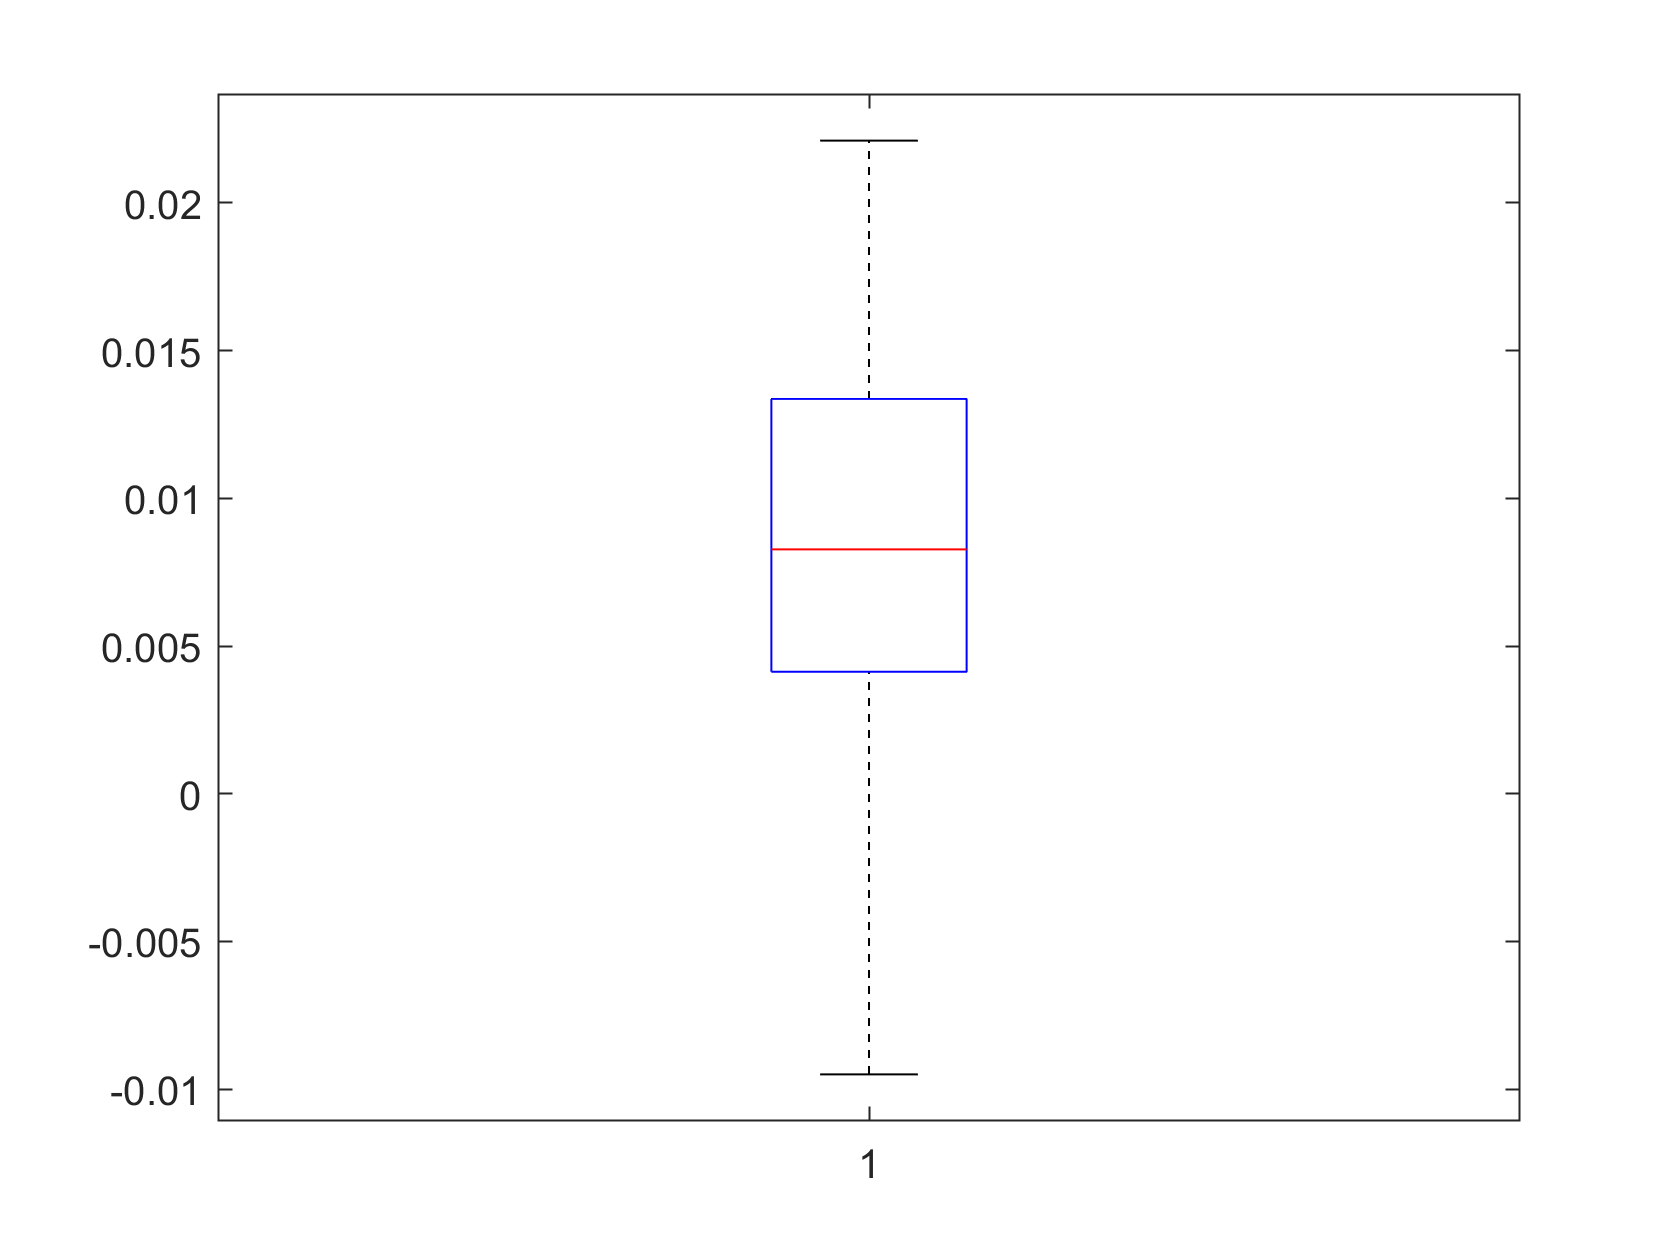

figure;
boxplot(dFF_per_reward)

So using for loops, we've been able to figure out that the fluorescence of this group of cells usually increases after  reward delivery, at approximately 0.01 dFF. 